# IET-GPR documentation

## Example 3

Migrate data from a GSSI-StructureScan Mini GPR.

### Start the IET-GPR software and load a GPR file

See Example 1 for details of this section.

clear
run('..\ietgpr')
filename = 'data\File____002.dzt';
[data, dataHeader] = readdzt(filename);
relPerm = 9;

### Remove the linear offset and apply a gain function

See Example 2 for details of this section.

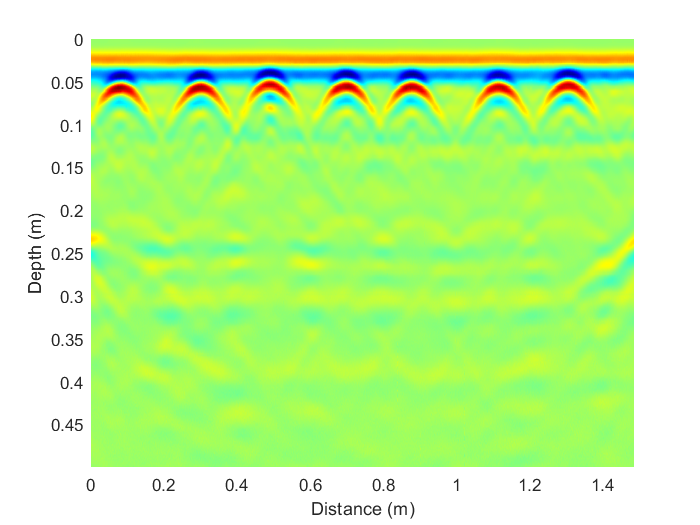

pdata = linearoffset(data);
pdata = iadgain1(pdata, 0.75);
plotbscan(pdata, dataHeader, relPerm);

### Reduce the amount of data

Resize (**resizescan** function) or trim (**trimscan** function) the data to reduce the computational complexity of the SAFT algotithm.

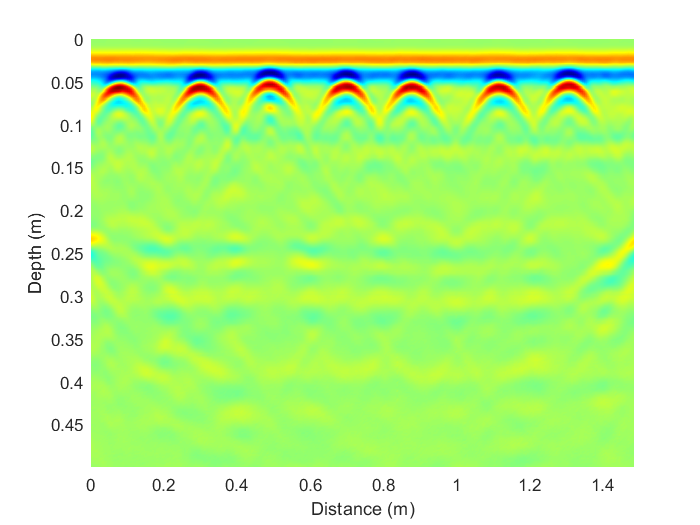

horSize = round(dataHeader.numOfColumns/4);
[pdata, pdataHeader] = resizescan(pdata, dataHeader, horSize);
plotbscan(pdata, pdataHeader, relPerm);

### Apply the SAFT migration algorithm

Apply the synthetic aperture focusing technique (SAFT) process to the data and plot the result.

[saft, saftHeader] = saftproc(pdata, pdataHeader, relPerm)

saft = 	1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0010    0.0011    0.0012
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0010

saftHeader = struct with fields:
    relPermittivity: 9
    samplesPerTrace: 254
      scansPerMeter: 200.1685
      startPosition: -0.4996
    nanosecPerTrace: 10
      depthPerTrace: 0.4997
       numOfColumns: 497
        numOfTraces: 297


As in example 1, the variable *saft* contains the SAFT data, while the variable *saftHeader* contains the SAFT general information. In addition to the information included in the GPR data header (*dataHeader*), the SAFT header (*saftHeader*) includes the relative permittivity (*relPermittivity*), the total depth in meters (*depthPerTrace*), and number of traces used for the SAFT (*numOfTraces*).

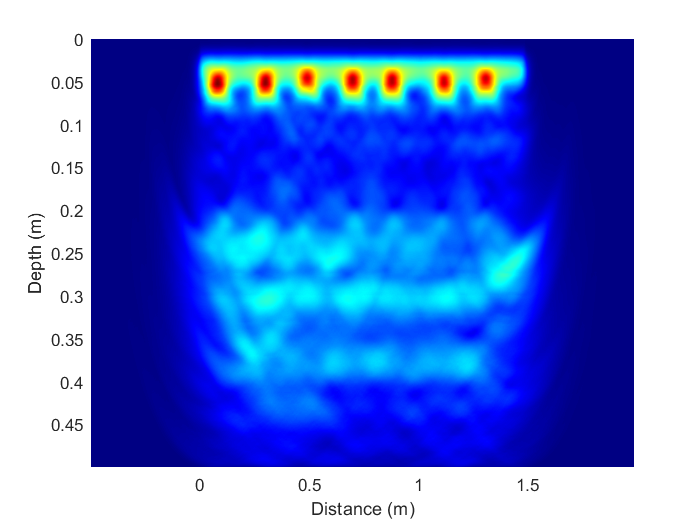

plotbscan(saft, saftHeader, relPerm);

Optionally, it is possible to use the **saftpost** function for trim or mirror the edges of the SAFT data.

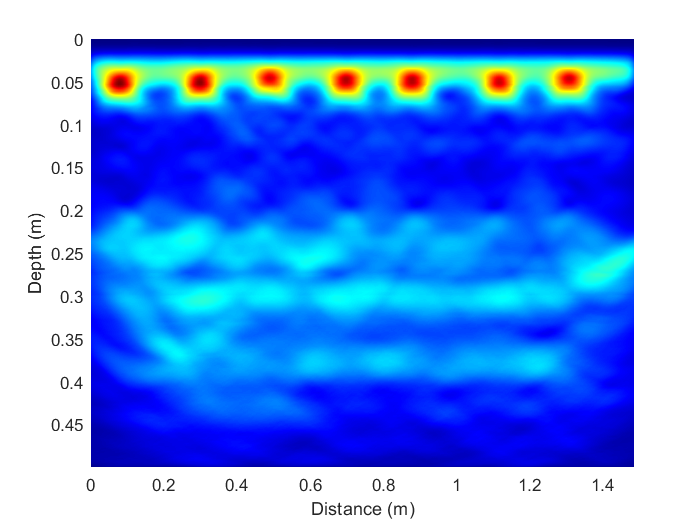

[saft, saftHeader] = saftpost(saft, saftHeader);
plotbscan(saft, saftHeader, relPerm);